# Obliczanie miejsc zerowych funkcji algebraicznych

## Metoda Bisekcji 

Wyznaczam nasza dokladnosc `e`, oraz nasze poczatki przedzialow.

clear all
close all
e = 0.01;
a = 1;
b = 5;
fun = @(x) sin(x);

przedstawiam `sin(x) `na wykresie

freq = a:1/100:b;
plot(freq,sin(freq))
title("Metoda bisekcji")
refline([0 0])

za pomoca zaimplementowanej funkcji `m_bisekcja() `obliczam miejsce zerowe funkcji `sin()`

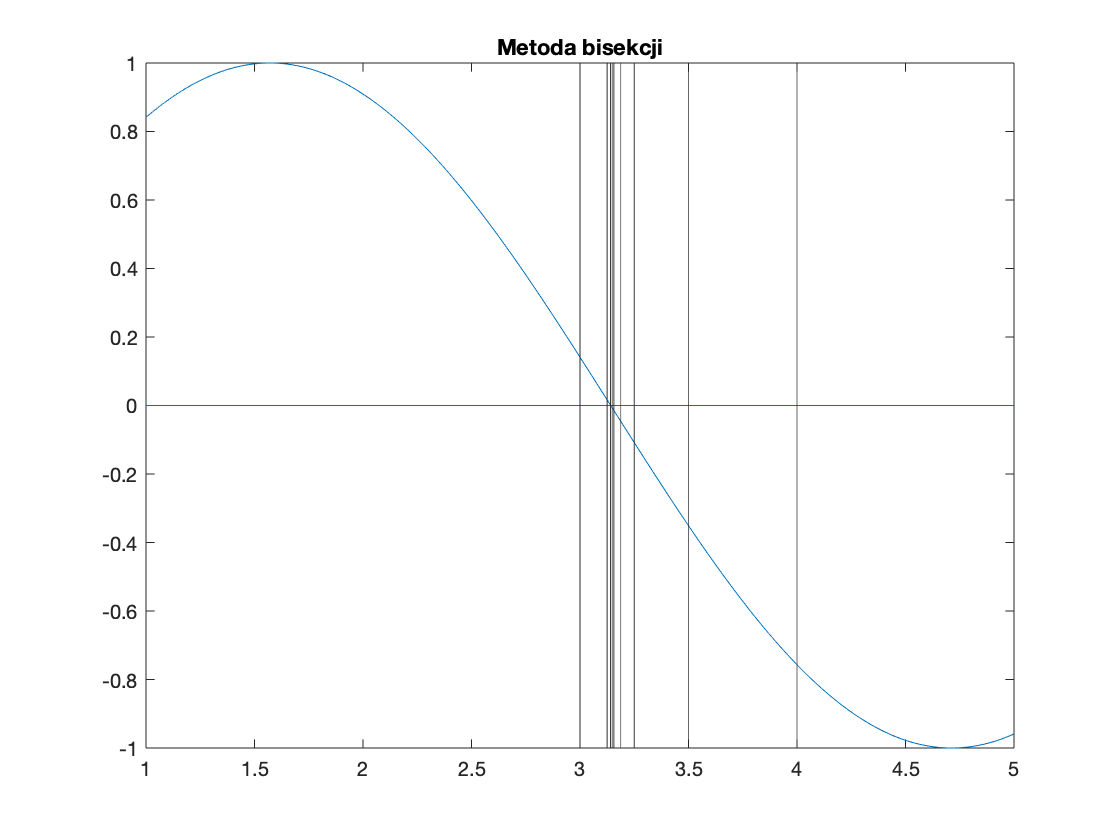

x0_bis = 3.1445

x0_bis = m_bisekcji(a, fun, b, e)

## Metoda regula-falsi

Funkcja musi byc rozniczkowalna na przedziale, mice dokladnei jeden pierwiastek na przedziale i na koncu przdzialu miec rozny znak.

clf(2)
figure(2)
plot(freq,sin(freq))
title("Metoda regula-falsi")
hold on
refline([0 0])

implementacja

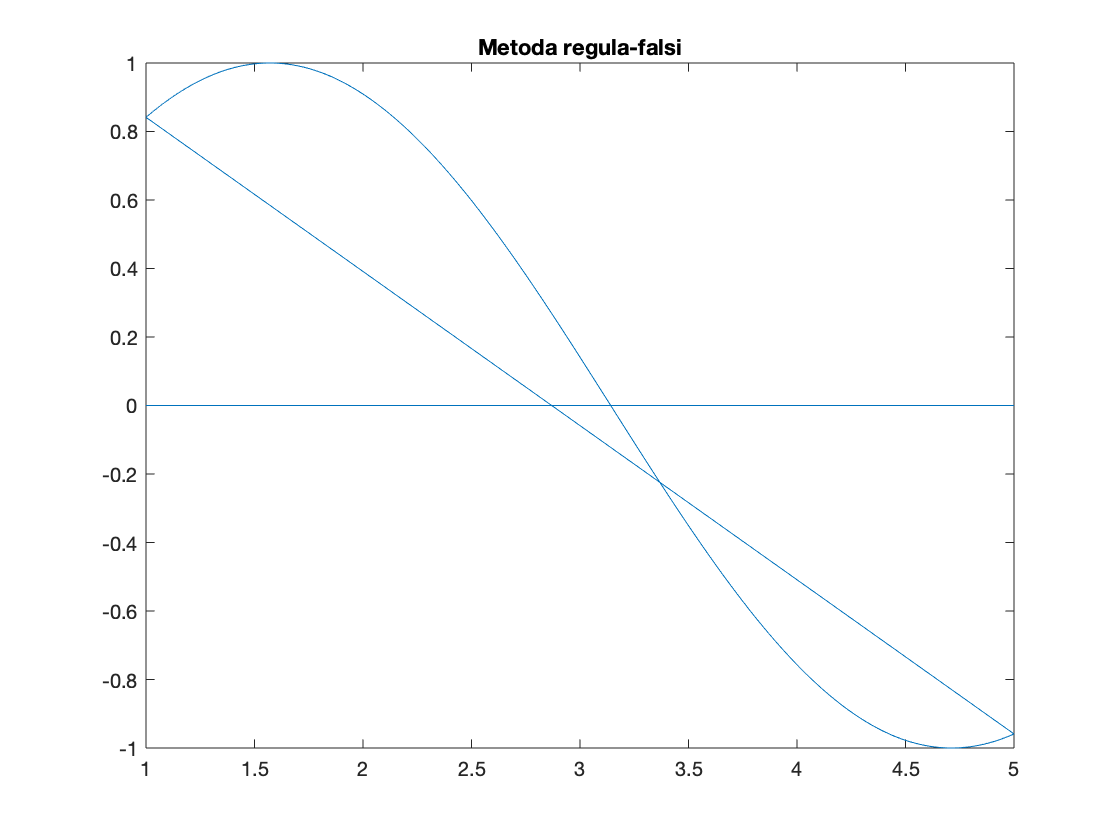

x0_fal = m_falsi(a, fun, b, e)

TODO

## Metoda siecznych

Nie wymaga rozniczkowalnosci funkcji

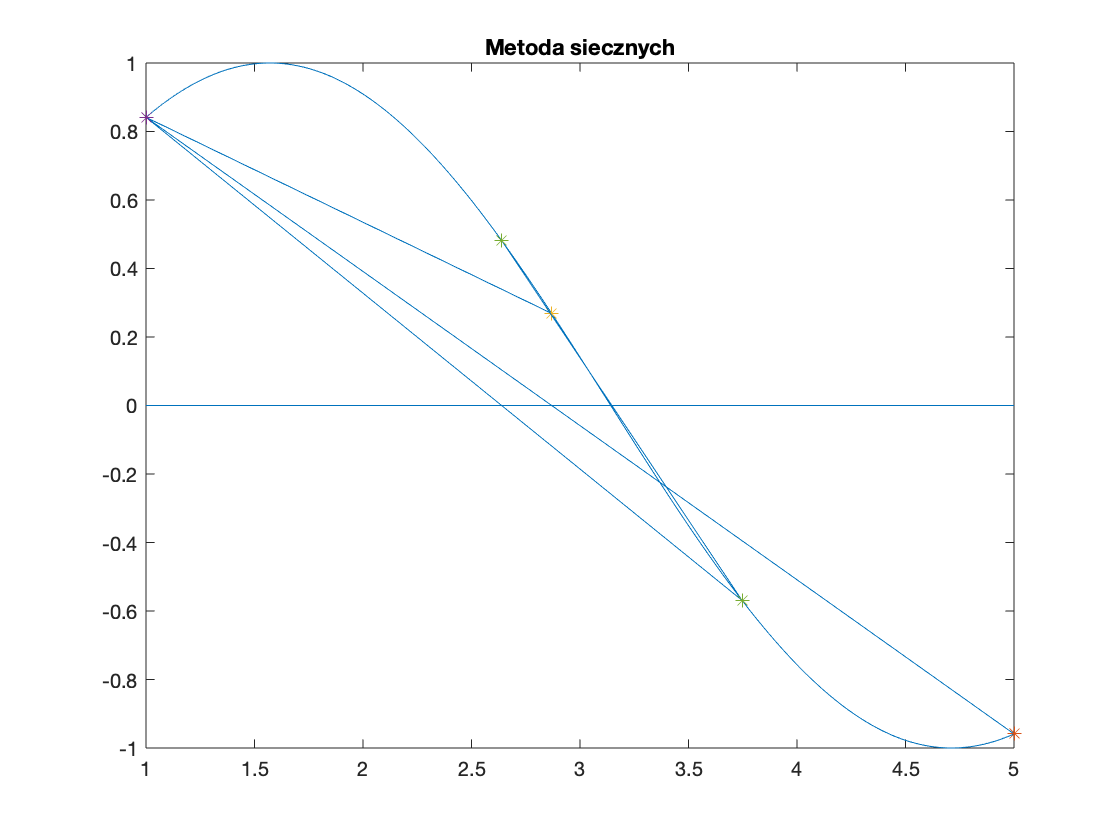

x0_sie = 3.1469

%clf(3)
figure(3)
plot(freq,sin(freq))
title("Metoda siecznych")
hold on
refline([0 0])

x0_sie = m_siecz(a, fun, b, e)

## Metoda iteracji Newtona-Raphsona

Funkcjamusi miec dokladnie jeden pierwiastek w przedziale, rozne znaki wartosci funkcji na krancach przedzialu i pierwsza i druga pochodna funkcji maja miec staly znak. Aby tak bylo zmniejszam przedzial do `<2,4.5>`

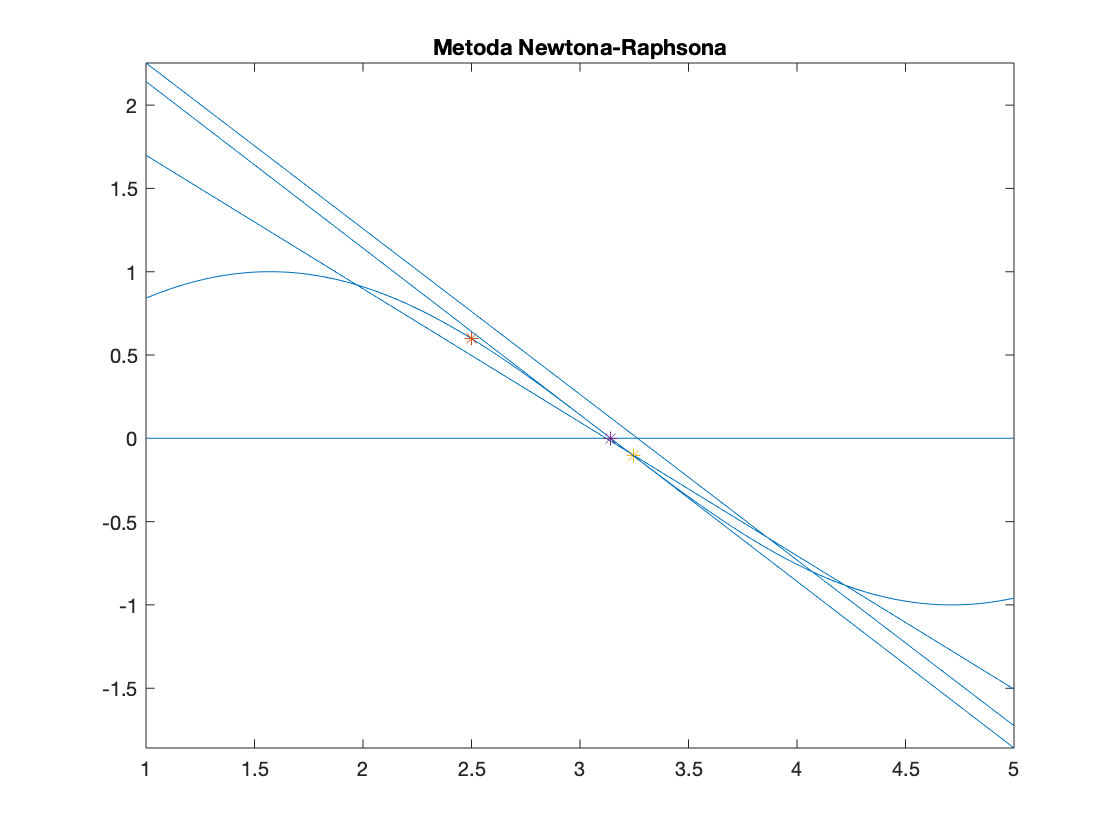

x0_new = 3.1412

p = 2.5;
funp = @(x) cos(x); % cos jest pierwsza pochodna sinusa

%clf(4)
figure(4)
plot(freq,sin(freq))
title("Metoda Newtona-Raphsona")
hold on
refline([0 0])

x0_new = m_newton(p , fun, funp, e)

zdefiniowane funkcje :

 metoda bisekcji:

function x0 = m_bisekcji(a, f, b, e)
    x0 = (a+b)/2;
    if f(x0)==0 || abs(a-b)<=e
        return
    end
    if f(a)*f(x0) < 0
        xline(a);
        xline(x0);
        x0 = m_bisekcji(a, f, x0, e);
    else
        xline(x0);
        xline(b);
        x0 = m_bisekcji(x0, f, b, e);
    end
end


metoda regula-falsi

function x0 = m_falsi(a, f, b, e)
    x0 = (a*f(b) - b*f(a))/(f(b)-(a));
    %x0 = f(b)*(b-a)/(f(b)-f(a));
    line([a b], [f(a) f(b)])
    if abs(f(x0))<=e
        return
    end
    if f(a)*f(x0) >= 0
       x1 = (x0*f(a) - a*f(x0))/(f(a)-(x0));
       x0 = m_falsi(a, f, x1, e);
    else
       x1 = (x0*f(b) - b*f(x0))/(f(b)-(x0));
       x0 = m_falsi(x1, f, b, e);
    end
    %x0 = m_falsi(x0, f, b, e);
    %x0 = m_falsi()
end

metoda siecznych

function x = m_siecz(a, f, b, e)
    line([a b], [f(a) f(b)])
    plot([a b], [f(a) f(b)],'*')
    x = b - f(b)*(b - a)/(f(b)-f(a));
    if abs(f(x))<=e
        return
    end
    if abs(x-a) < abs(x-b)
        x = m_siecz(a, f, x, e);
    else
        x = m_siecz(x, f, a, e);
    end
end

metoda iteracji Newtona-Raphsona

function p = m_newton(p, f, fp, e)
    refline([fp(p),p])
    plot(p, f(p),'*')
    if abs(f(p)) < e
        return
    end
    p = m_newton(p - f(p)/fp(p), f, fp, e);
end